# EngineFaultDB: Automotive Engine Fault Classification

## Data Preparation

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
data = readtable(Data_location, 'VariableNamingRule', 'preserve');
data_fault0 = data(1:16000, :);
data_fault1 = data(16001:26998, :);
data_fault2 = data(26999:41998, :);
data_fault3 = data(41999:end, :);

data.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


% Data Length Configuration
L0 = height(data_fault0); % Fault 0 : 16,000
L1 = height(data_fault1); % Fault 1 : 10,988
L2 = height(data_fault2); % Fault 2 : 15,000
L3 = height(data_fault3); % Fault 3 : 14,001

% Sampling Freq
fs = 10;

### Data Division

div = 1:1000;
fault0 = data_fault0(div, :);
fault1 = data_fault1(div, :);
fault2 = data_fault2(div, :);
fault3 = data_fault3(div, :);

## Correlation Check

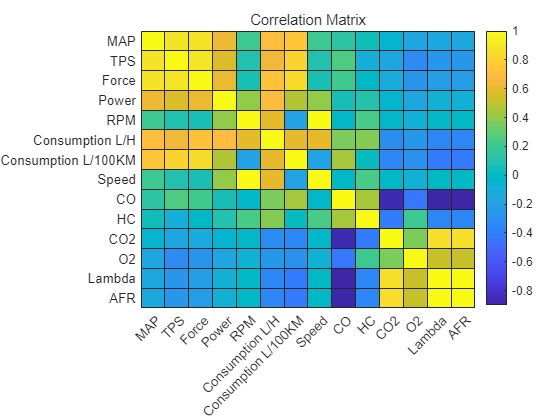

variable_names = data.Properties.VariableNames(2:15);
corr_matrix = corrcoef(table2array(data(:, 2:15)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8842    0.8801    0.6295    0.2014    0.6978    0.7396    0.2011    0.1347    0.0446   -0.0497   -0.1577   -0.1448   -0.1448
    0.8842    1.0000    0.8915    0.5826    0.0929    0.6478    0.8069    0.0927    0.2538   -0.0984   -0.1640   -0.3308   -0.2612   -0.2612
    0.8801    0.8915    1.0000    0.6214    0.0725    0.7198    0.8484    0.0719    0.2167   -0.0025   -0.1259   -0.2742   -0.2312   -0.2312
    0.6295    0.5826    0.6214    1.0000    0.4036    0.6952    0.4730    0.4059    0.0606    0.1013   -0.0413   -0.1616   -0.0788   -0.0788
    0.2014    0.0929    0.0725    0.4036    1.0000    0.6035   -0.1977    0.9969   -0.0202    0.2365   -0.0159   -0.0800   -0.0046   -0.0045
    0.6978    0.6478    0.7198    0.6952    0.6035    1.0000    0.6141    0.6033    0.3588    0.3754   -0.3134   -0.2518   -0.3476   -0.3475
    0.7396    0.8069    0.8484    0.4730   -0.1977    0.6141    1.0000   -0.1972    0.4414    0.0273   -0.3498   -0.2904   -0.4127   -0.4127
    0.2011   

### 연관성 높은 Variables 제거

corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold

high_corr = 14×14 logical 배열
   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   1   0   0   0   0


high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

remove_vars = unique(max(rows, cols));
variable_names = data.Properties.VariableNames(2:15);
vars_to_remove = variable_names(remove_vars);

data(:, remove_vars + 1) = [];

disp(['Removed variables: ', strjoin(vars_to_remove, ', ')]);

Removed variables: TPS, Force, Consumption L/100KM, Speed, CO2, Lambda, AFR


## Time Domain Anaylsis

### MAP

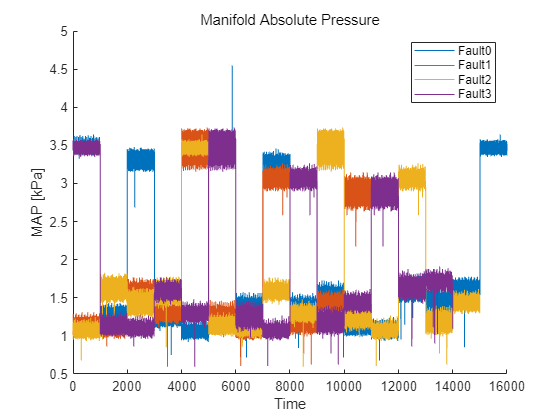

figure;
hold on;
plot((1:L0), data.MAP(1:L0, :));
plot((1:L1), data.MAP(L0+1:L0+L1, :));
plot((1:L2), data.MAP(L1+1:L1+L2, :));
plot((1:L3), data.MAP(L2+1:L2+L3, :));
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("Manifold Absolute Pressure");

% mdl_svm = fitcecoc(X_train, Y_train, 'ClassNames',{'0','1','2','3'})

% mlResubErr_svm = resubLoss(mdl_svm)

% f0_MAP = rescale(data_fault0.MAP);
% f1_MAP = rescale(data_fault1.MAP);
% f2_MAP = rescale(data_fault2.MAP);
% f3_MAP = rescale(data_fault3.MAP);
% 
% figure;
% hold on;
% plot(1:2000, f0_MAP(1:2000, :));
% plot(1:2000, f1_MAP(1:2000, :));
% plot(1:2000, f2_MAP(1:2000, :));
% plot(1:2000, f3_MAP(1:2000, :));
% legend("f0", "f1", "f2", "f3");


% figure();
% t = 1:16000;
% Force = table2array(data(1:16000, 4));
% Power = table2array(data(1:16000, 5));
% Speed = table2array(data(1:16000, 9));
% 
% hold on;
% subplot(3,1,1);
% plot(t, Force);
% title("Force - Healthy Engine");
% ylabel("N");
% xlabel("sampling time");
% legend("Force")
% 
% subplot(3,1,2);
% plot(t, Power);
% title("Power - Healthy Engine");
% ylabel("Nm");
% xlabel("sampling time");
% legend("Power")
% 
% subplot(3,1,3);
% plot(t, Speed);
% title("Speed - Healthy Engine");
% ylabel("m/s");
% xlabel("sampling time");
% legend("Speed")
% 
% hold off;

% t_2=1:2000;
% RPM_fault1 = table2array(data(16001:16001+1999, 6));
% plot(t_2,RPM_fault1);